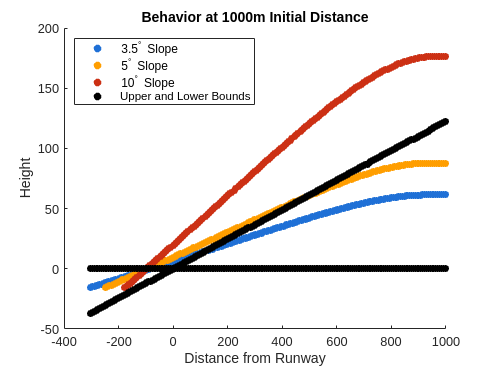

clear variables; close all; clc;
runway_height = 376;
slope = tand(3.5);
color_bounds = "black";
color_3 = [0.122, 0.439, 0.839];
color_5 = [1 0.62 0];
color_10 = [0.8, 0.188, 0.078];

% Load in all datasets for each distance and angle

data_1000_3 = readtable("/home/achadbo/Desktop/Autoland/7-10-2024/1000/3.5/states.csv");
data_1000_5 = readtable("/home/achadbo/Desktop/Autoland/7-10-2024/1000/5/states.csv");
data_1000_10 = readtable("/home/achadbo/Desktop/Autoland/7-10-2024/1000/10/states.csv");

data_3000_3 = readtable("/home/achadbo/Desktop/Autoland/7-10-2024/3000/3.5/states.csv");
data_3000_5 = readtable("/home/achadbo/Desktop/Autoland/7-10-2024/3000/5/states.csv");
data_3000_10 = readtable("/home/achadbo/Desktop/Autoland/7-10-2024/3000/10/states.csv");

data_5000_3 = readtable("/home/achadbo/Desktop/Autoland/7-10-2024/5000/3.5/states.csv");
data_5000_5 = readtable("/home/achadbo/Desktop/Autoland/7-10-2024/5000/5/states.csv");
data_5000_10 = readtable("/home/achadbo/Desktop/Autoland/7-10-2024/5000/10/states.csv");


% Grab the runway dist and height from each distance and angle

x_1000_3 = data_1000_3.x;
h_1000_3 = data_1000_3.h - runway_height;
x_1000_5 = data_1000_5.x;
h_1000_5 = data_1000_5.h - runway_height;
x_1000_10 = data_1000_10.x;
h_1000_10 = data_1000_10.h - runway_height;

x_3000_3 = data_3000_3.x;
h_3000_3 = data_3000_3.h - runway_height;
x_3000_5 = data_3000_5.x;
h_3000_5 = data_3000_5.h - runway_height;
x_3000_10 = data_3000_10.x;
h_3000_10 = data_3000_10.h - runway_height;

x_5000_3 = data_5000_3.x;
h_5000_3 = data_5000_3.h - runway_height;
x_5000_5 = data_5000_5.x;
h_5000_5 = data_5000_5.h - runway_height;
x_5000_10 = data_5000_10.x;
h_5000_10 = data_5000_10.h - runway_height;


% Calculate r and upper bounds for each distance (based on desired angle)

slope_x_1000 = x_1000_3.*slope;
r_1000 = slope * sqrt(x_1000_3.^2 + slope_x_1000.^2);
u_bounds_1000 = slope_x_1000 + r_1000;
l_bounds_1000 = slope_x_1000 - r_1000;

slope_x_3000 = x_3000_3.*slope;
r_3000 = slope * sqrt(x_3000_3.^2 + slope_x_3000.^2);
u_bounds_3000 = slope_x_3000 + r_3000;
l_bounds_3000 = slope_x_3000 - r_3000;

slope_x_5000 = x_5000_3.*slope;
r_5000 = slope * sqrt(x_5000_3.^2 + slope_x_5000.^2);
u_bounds_5000 = slope_x_5000 + r_5000;
l_bounds_5000 = slope_x_5000 - r_5000;


% Plot each distance

scatter(x_1000_3, h_1000_3, 30, color_3, "filled");
hold on;
scatter(x_1000_5, h_1000_5, 30, color_5, "filled");
scatter(x_1000_10, h_1000_10, 30, color_10, "filled");
scatter(x_1000_3, u_bounds_1000, 30, color_bounds, "filled");
scatter(x_1000_3, l_bounds_1000, 30, color_bounds, "filled");
xlabel("Distance from Runway");
ylabel("Height");
title("Behavior at 1000m Initial Distance");
legend({"3.5^{\circ} Slope", "5^{\circ} Slope", "10^{\circ} Slope", "Upper and Lower Bounds"}, 'Location', 'northwest');
hold off;

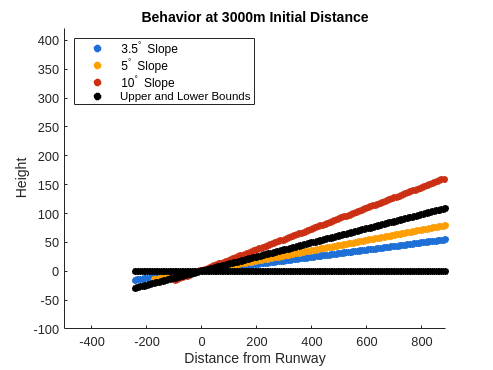


scatter(x_3000_3, h_3000_3, 30, color_3, "filled");
hold on;
scatter(x_3000_5, h_3000_5, 30, color_5, "filled");
scatter(x_3000_10, h_3000_10, 30, color_10, "filled");
scatter(x_3000_3, u_bounds_3000, 30, color_bounds, "filled");
scatter(x_3000_3, l_bounds_3000, 30, color_bounds, "filled");
xlabel("Distance from Runway");
ylabel("Height");
title("Behavior at 3000m Initial Distance");
legend({"3.5^{\circ} Slope", "5^{\circ} Slope", "10^{\circ} Slope", "Upper and Lower Bounds"}, 'Location', 'northwest');
hold off;

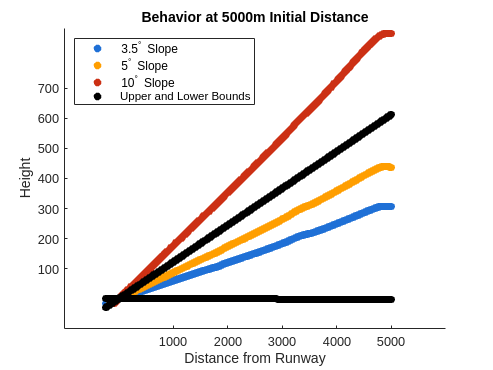


scatter(x_5000_3, h_5000_3, 30, color_3, "filled");
hold on;
scatter(x_5000_5, h_5000_5, 30, color_5, "filled");
scatter(x_5000_10, h_5000_10, 30, color_10, "filled");
scatter(x_5000_3, u_bounds_5000, 30, color_bounds, "filled");
scatter(x_5000_3, l_bounds_5000, 30, color_bounds, "filled");
xlabel("Distance from Runway");
ylabel("Height");
title("Behavior at 5000m Initial Distance");
legend({"3.5^{\circ} Slope", "5^{\circ} Slope", "10^{\circ} Slope", "Upper and Lower Bounds"}, 'Location', 'northwest');
hold off;